% Drone and Ocean Acoustic Noise Simulation
clear; clc;

% --- 1. SETTINGS ---
fs = 44100;           % Audio sampling rate (Hz)
dur = 5.0;            % Duration in seconds
t = 0:1/fs:dur-1/fs;  % Time vector

fprintf('Synthesizing 5 seconds of Ocean and Drone noise...\n');

Synthesizing 5 seconds of Ocean and Drone noise...



% --- 2. OCEAN NOISE SYNTHESIS ---
% Start with raw white noise (all frequencies equally loud)
ocean_raw = randn(1, length(t));

% The ocean is "heavy", so we use a Low-Pass Filter to cut off the highs.
% Keeping everything below 800 Hz.
[b_ocean, a_ocean] = butter(4, 800/(fs/2), 'low'); 
ocean_noise = filter(b_ocean, a_ocean, ocean_raw);

% Normalize ocean noise
ocean_noise = ocean_noise / max(abs(ocean_noise));


% --- 3. DRONE NOISE SYNTHESIS ---
% A quadcopter hovering typically spins its props around 6000-8000 RPM.
% For a 2-blade prop at 7500 RPM, the fundamental acoustic frequency is:
% (7500 / 60) * 2 = 250 Hz.
fund_freq = 250; 
drone_motor = zeros(1, length(t));

% Generate the fundamental whine and its harmonics (overtones)
% The harmonics get quieter as they go up in pitch
for h = 1:12
    drone_motor = drone_motor + (1/h) * sin(2 * pi * (fund_freq * h) * t);
end

% Add "Prop Wash" (the buzzing sound of the blades tearing the air)
% This is broadband noise filtered to the mid-frequencies
prop_wash = randn(1, length(t));
[b_wash, a_wash] = butter(4, [1000 3000]/(fs/2), 'bandpass');
prop_wash = filter(b_wash, a_wash, prop_wash);

% Combine motor harmonics and prop wash
drone_noise = drone_motor + (0.8 * prop_wash);
drone_noise = drone_noise / max(abs(drone_noise));


% --- 4. MIXING THE ENVIRONMENT ---
% Because the mic is ON the drone, the drone is vastly louder than the ocean.
ocean_vol = 0.15;  % 15% volume
drone_vol = 0.85;  % 85% volume

% Mix them together
ambient_environment = (ocean_noise * ocean_vol) + (drone_noise * drone_vol);

% Prevent digital clipping
ambient_environment = ambient_environment / max(abs(ambient_environment));


% --- 5. AUDIO PLAYBACK ---
disp('Playing simulation over speakers...');

Playing simulation over speakers...


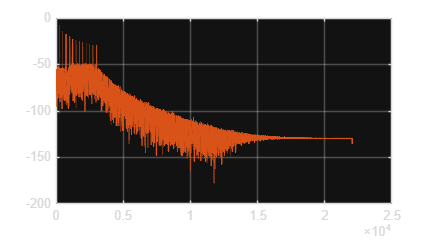

% Fade in/out to prevent pops
fade = round(fs * 0.1); 
env = ones(1, length(ambient_environment));
env(1:fade) = linspace(0, 1, fade);
env(end-fade+1:end) = linspace(1, 0, fade);
sound(ambient_environment .* env * 0.8, fs);


% --- 6. FREQUENCY SPECTRUM PLOT (FFT) ---
% Calculate the Fast Fourier Transform to analyze the frequencies
N = length(ambient_environment);
Y = fft(ambient_environment);
P2 = abs(Y/N);            % Two-sided spectrum
P1 = P2(1:N/2+1);         % Single-sided spectrum
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(N/2))/N;       % Frequency domain vector

% Plotting
figure('Name', 'Drone Microphone Frequency Analysis', 'Color', 'w', 'Position', [100, 100, 900, 500]);

% Convert amplitude to Decibels (dB) for a realistic acoustic view
plot(f, 20*log10(P1), 'Color', '#D95319', 'LineWidth', 1.2);
hold on; grid on;


% Highlight the drone's target filter zone (where the whistle will eventually go)
patch([3400 3700 3900 3900 3700 3400], [-120 -120 0 0], [0.4660 0.6740 0.1880], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', 'Target Filter Zone (3.4 - 3.9 kHz)');

Error using patch
Specify the coordinates as matrices of the same size or as vectors with the same number of elements.


% Formatting the plot
title('Frequency Spectrum of Drone Mics (No Whistle Present)', 'FontSize', 14);
xlabel('Frequency (Hz)', 'FontSize', 12, 'FontWeight', 'bold');
ylabel('Magnitude (dB)', 'FontSize', 12, 'FontWeight', 'bold');

% Zoom in on the relevant acoustic range
xlim([0 5000]); 
ylim([-100 -20]);

% Label the massive drone harmonics
text(fund_freq, -25, '\leftarrow Drone Fundamental', 'FontSize', 10, 'FontWeight', 'bold');
text(fund_freq*3, -35, '\leftarrow Motor Harmonics', 'FontSize', 10);

legend('Ambient Noise Profile', 'Rescue Filter Window');
hold off;